s = tf('s')

s =
 
  s
 
Continuous-time transfer function.



a = 156.4

a = 156.4000

b = 1.7

b = 1.7000

c = 71.93

c = 71.9300

G = a/(s^2+b*s+c)

G =
 
         156.4
  -------------------
  s^2 + 1.7 s + 71.93
 
Continuous-time transfer function.



ev = 0.9

ev = 0.9000

kiLim = 1/(2.1743*ev)

kiLim = 0.5110

ts = 10

ts = 10

as = 4.5/ts

as = 0.4500

Mp = 0.3

Mp = 0.3000

zeta = sqrt((log(Mp)^2)/(pi^2+(log(Mp)^2)))

zeta = 0.3579



%PI
%Seleccionando kp
kp = 0.4%0.0009

kp = 0.4000

GrlPI = a/(s*(s^2+b*s+c+a*kp))

GrlPI =
 
           156.4
  -----------------------
  s^3 + 1.7 s^2 + 134.5 s
 
Continuous-time transfer function.





polos=pole(GrlPI)

polos =    0.0000 + 0.0000i
  -0.8500 +11.5658i
  -0.8500 -11.5658i


ceros = zero(GrlPI)


ceros =

  0×1 empty double column vector



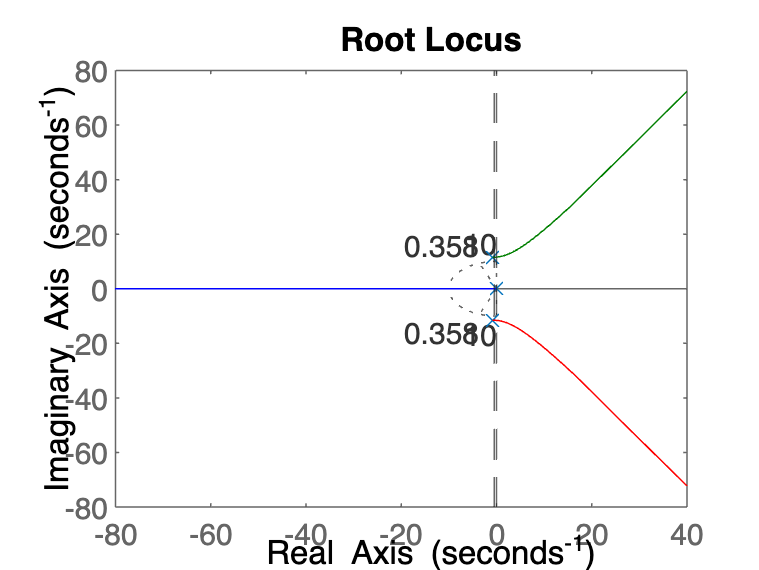


figure()
rlocus(GrlPI)
xline(-as,'--')
xline(0,'--')
sgrid(zeta,10)


%Seleccionamos ki
ki = 0.65%0.3

ki = 0.6500

ev = 1/(2.1743*ki)

ev = 0.7076


C = kp+ki/s

C =
 
  0.4 s + 0.65
  ------------
       s
 
Continuous-time transfer function.



Go = C*G/(1+C*G)

Go =
 
           62.56 s^4 + 208 s^3 + 4673 s^2 + 7312 s
  ---------------------------------------------------------
  s^6 + 3.4 s^5 + 209.3 s^4 + 452.6 s^3 + 9847 s^2 + 7312 s
 
Continuous-time transfer function.



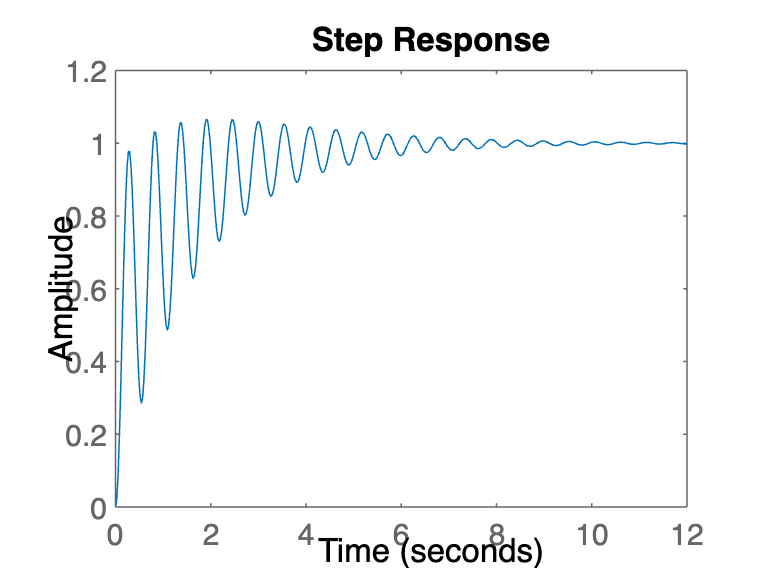

step(Go)

stepinfo(Go)

ans = struct with fields:
         RiseTime: 0.1740
    TransientTime: 6.5923
     SettlingTime: 6.5923
      SettlingMin: 0.2857
      SettlingMax: 1.0650
        Overshoot: 6.5035
       Undershoot: 0
             Peak: 1.0650
         PeakTime: 1.9013



GrlPID = (a*s^2)/(a*ki+c*s+b*s^2+s^3+a*kp*s)

GrlPID =
 
             156.4 s^2
  -------------------------------
  s^3 + 1.7 s^2 + 134.5 s + 101.7
 
Continuous-time transfer function.




polos=pole(GrlPID)

polos =   -0.4700 +11.5566i
  -0.4700 -11.5566i
  -0.7599 + 0.0000i


ceros = zero(GrlPID)

ceros =      0
     0


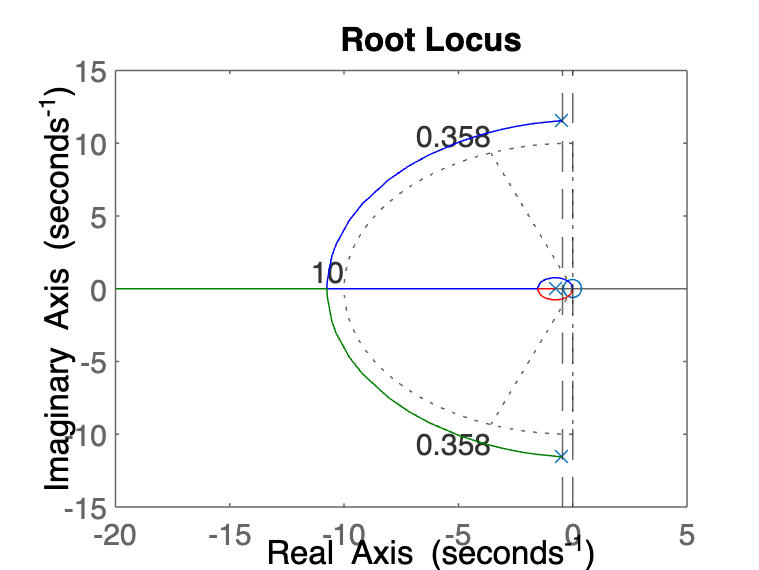


figure()
rlocus(GrlPID)
xline(-as,'--')
xline(0,'--')
sgrid(zeta,10)

%Seleccionamos kd
kd=0.0098%0.00323

kd = 0.0098

N=100;
C=kp+ki/s+kd*(N/(1+N*(1/s)))

C =
 
  1.38 s^2 + 40.65 s + 65
  -----------------------
        s^2 + 100 s
 
Continuous-time transfer function.



CD = c2d(C,1E-03)

CD =
 
  1.38 z^2 - 2.721 z + 1.341
  --------------------------
    z^2 - 1.905 z + 0.9048
 
Sample time: 0.001 seconds
Discrete-time transfer function.



Go = C*G/(1+C*G)

Go =
 
            215.8 s^6 + 2.831e04 s^5 + 7.09e05 s^4 + 4.124e06 s^3 + 4.819e07 s^2 + 7.312e07 s
  ------------------------------------------------------------------------------------------------------
  s^8 + 203.4 s^7 + 1.104e04 s^6 + 9.19e04 s^5 + 2.231e06 s^4 + 7.605e06 s^3 + 9.993e07 s^2 + 7.312e07 s
 
Continuous-time transfer function.



polos = pole(Go)

polos =    0.0000 + 0.0000i
-100.0000 + 0.0000i
 -98.4375 + 0.0000i
  -1.2479 +11.5385i
  -1.2479 -11.5385i
  -0.8500 + 8.4385i
  -0.8500 - 8.4385i
  -0.7667 + 0.0000i


zeros = zero(Go)

zeros = 1.0e+02 *

   0.0000 + 0.0000i
  -1.0000 + 0.0000i
  -0.2776 + 0.0000i
  -0.0085 + 0.0844i
  -0.0085 - 0.0844i
  -0.0170 + 0.0000i


stepinfo(Go)

ans = struct with fields:
         RiseTime: 1.7869
    TransientTime: 4.4064
     SettlingTime: 4.4064
      SettlingMin: 0.8638
      SettlingMax: 1.0000
        Overshoot: 0
       Undershoot: 0
             Peak: 1.0000
         PeakTime: 16.2144


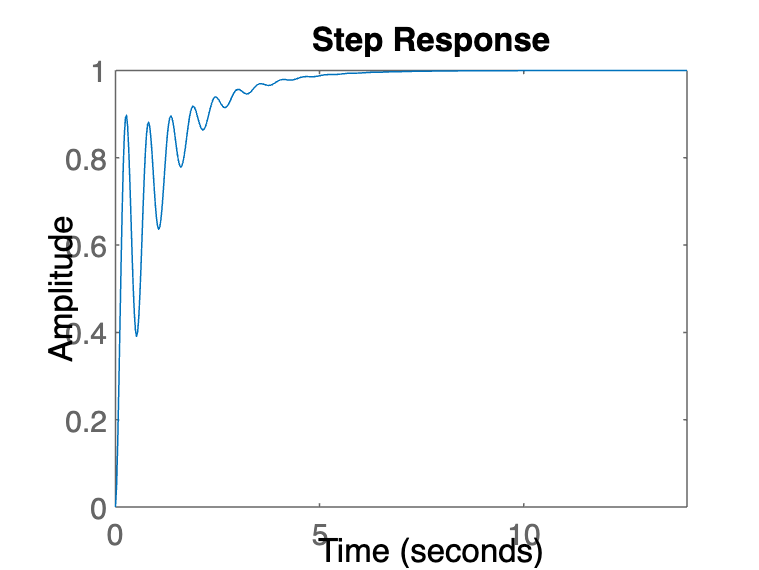

step(Go)




[Gm Pm Wcg Wcp] = margin(C*G)

Gm = Inf

Pm = 25.2776

Wcg = Inf

Wcp = 11.5785

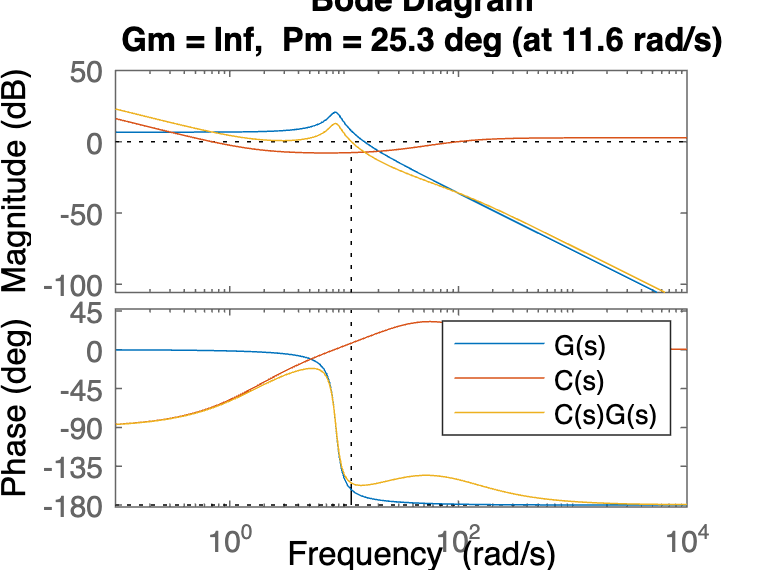


figure()
bode(G)
hold on
bode(C)
margin(C*G)
hold off
legend('G(s)','C(s)', 'C(s)G(s)')



% %PI variando ki
% GrlPI = a/(s*(s^2+b*s+c+a*kp))
% 
% polos=pole(GrlPI)
% ceros = zero(GrlPI)
% 
% figure()
% rlocus(GrlPI)
% xline(-as,'--')
% sgrid(zeta,10)
% 
% ki=10
% C=kp+ki/s
% Go = C*G/(1+C*G)
% stepinfo(Go)